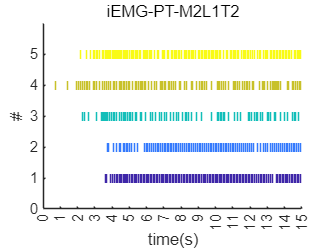

% KYM 2024/11/22
% 用途:用iPTt用来trigger表面肌电的MUAP
% 说明:
% iPT用2048Hz的采样率eaf文件转换，sEMG使用的是经过滤波后的表面肌电（不滤通道）
fsamp=2048;
motion=2;
level=1;
trial=2;
% eafpath=['Z:\Result\24-10-12iEMG-sEMG\M' num2str(motion) 'L' num2str(level) 'T' num2str(trial) '.eaf'];
eafpath = ['Z:\data\24-6-21iEMG-US-sEMG联合采集_康亦铭右肱二头\signal\iEMG_sEMG_US肌电后处理\iEMG_HDsEMG_S1_M' num2str(motion) '_level' num2str(level) '_trial' num2str(trial) '_24-06-21_UUS.eaf'];%iPT
% eafpath=['Z:\data\24-7-30iEMG-sEMG联合采集_陈晨右前臂肱桡肌\肌内肌电anneaf\xEMG-L' num2str(2.5*level) 'T' num2str(trial) '.eaf'];
% eafpath=['Z:\Result\24-08-22iEMG-US-sEMG联合采集__胡康生右肱二头肌\M' num2str(motion) 'L' num2str(level) 'T' num2str(trial) '.eaf'];
% eafpath=['Z:\Result\24-08-29iEMG-US-sEMG联合采集_程瑞佳\eaf\M' num2str(motion) 'L' num2str(level) 'T' num2str(trial) '.eaf'];
iPT=eaf2pulse(eafpath,fsamp);


clf;
pic=draw_PluseTime(iPT,fsamp,1,30);
title(['iEMG-PT-M' num2str(motion) 'L' num2str(level) 'T' num2str(trial)])



%计算muap
% datafilt=CKCdecomp{motion,trial}.datafilt;
datafilt=decompData;
% datafilt=downsample(data_EMG(2:65,:)',5)';
[sigcell]=sig2cell(datafilt,4);%%%%%%%%%%%%  5*13-type4 8*8ot-type6
[muaparray,~]=muapExtraction(sigcell,iPT,100,'STA');

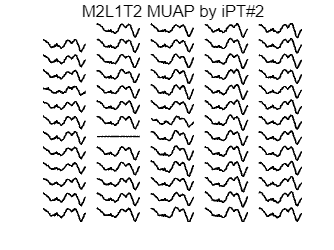

which2show=2;
clf;
muap_recon=muap_pca(muaparray{which2show},0.95);
%%%去除明显有问题的电极
% for i=[1:6] muap_recon{i,1}=[]; end
% muap_recon{3,4}=[];
% muap_recon{13,5}=[];


figure
plotArrayPotential(muap_recon,1,1);
title(['M' num2str(motion) 'L' num2str(level) 'T' num2str(trial) ' MUAP by iPT#' num2str(which2show) ])

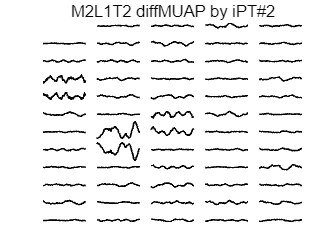

figure;
plotArrayPotential(muap_recon,2,1);
title(['M' num2str(motion) 'L' num2str(level) 'T' num2str(trial) ' diffMUAP by iPT#' num2str(which2show)])